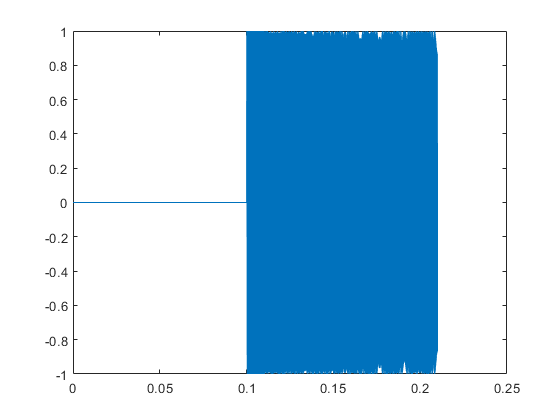

% 原始信号
Fs = 48000;
fBegin = 2000;
fEnd = 8000;
chirpTimeMs = 100;
origin = generateChirp(Fs, fBegin, fEnd, chirpTimeMs, 10);
origin_1 = [zeros(Fs * 0.1, 1);origin];
figure;
plot((0:length(origin_1)-1)/Fs, origin_1);

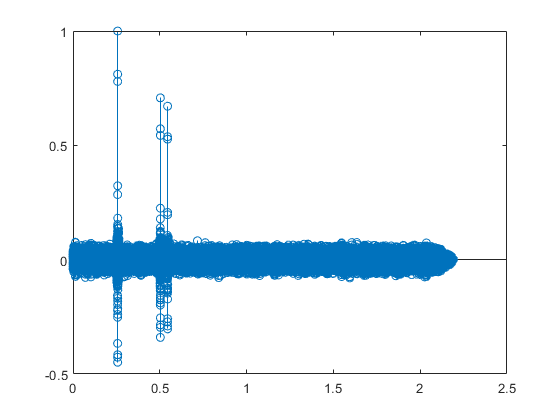

A = 100000;
origin_1 = [zeros(12345, 1);origin;zeros(A-12345, 1)];

origin_2 = [zeros(24152, 1);origin;zeros(A-24152, 1)] * 0.7;
origin_3 = [zeros(26153, 1);origin;zeros(A-26153, 1)] * 0.65;

t = origin_1 + origin_2 + origin_3;
t = t + randn(length(t), 1);

[c, lags] = correlation_cc(t, origin, Fs);
figure;
stem(lags, c);

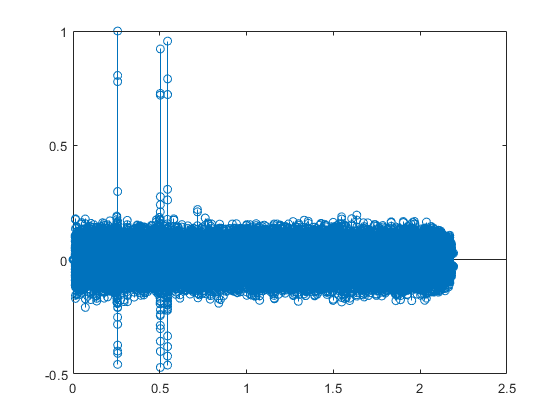


[c1, lags1] = correlation_normalize(c, lags, origin);
figure;
stem(lags1, c1);